# Experiment 1_2

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

Parsa Salehi - 40023048

### clear workspace

clc;
clear;
close all;

## Part 6: aliasing in time domein

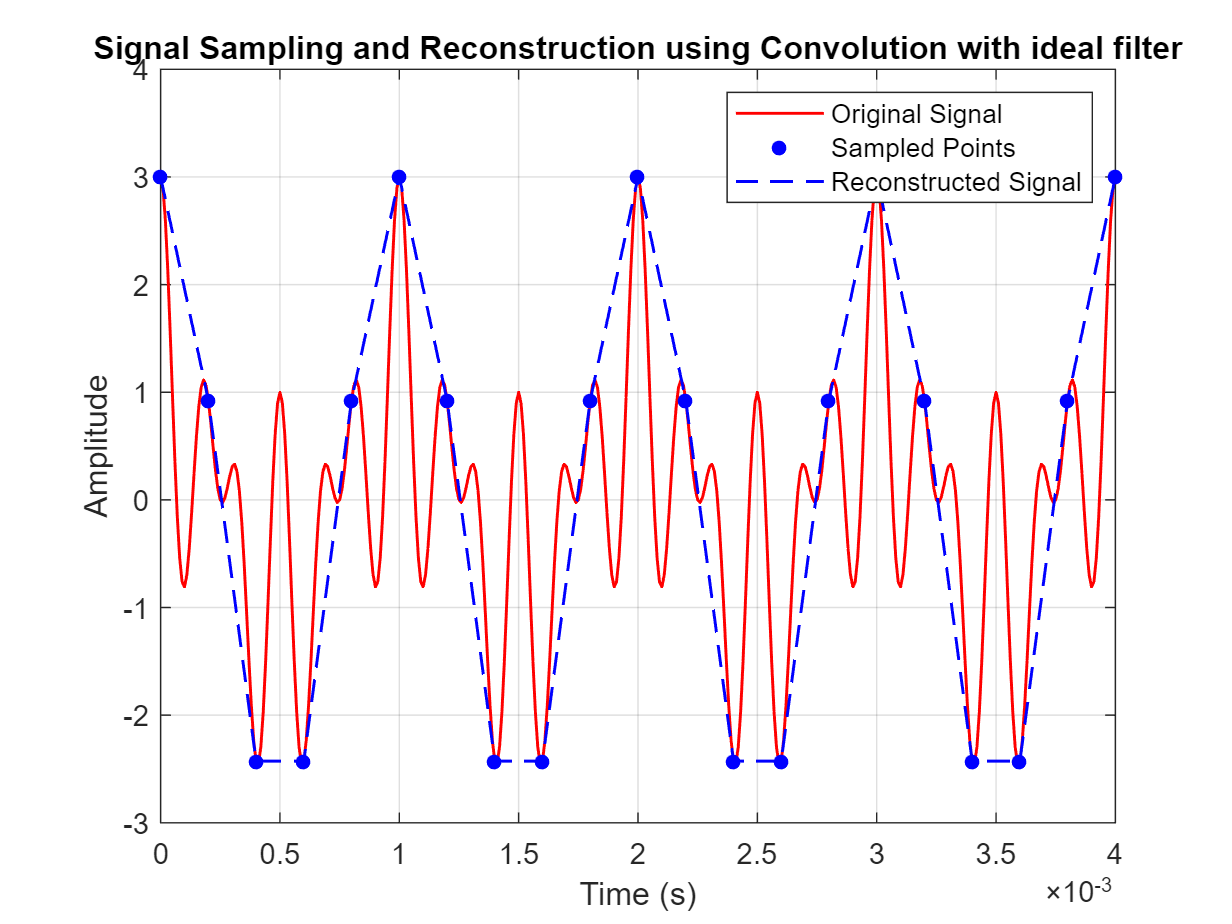

Ts = 0.00001;
t = 0:Ts:0.004;
x = cos(2*pi*1e3*t) + cos(8*pi*1e3*t) + cos(12*pi*1e3*t);
figure("Name", "original signal");
plot(t, x, LineWidth=1, Color='r');
title("original signal with samples");
hold on;
fs_low = 5e3;
t_sampled = 0:1/fs_low:0.004;
x_sampled = cos(2*pi*1e3*t_sampled) + cos(8*pi*1e3*t_sampled) + cos(12*pi*1e3*t_sampled);
plot(t_sampled, x_sampled, '.b', 'MarkerSize', 15);

% Reconstruction
L = 50; % reconstruction filter length
t_sinc = -L:1/fs_low:L;
sinc_filter = sinc(fs_low * t_sinc);

x_reconstructed_discrete = conv(x_sampled, sinc_filter, 'same'); 
t_reconstructed = linspace(0, 0.004, length(x_reconstructed_discrete));

plot(t_reconstructed, x_reconstructed_discrete, '--b', 'LineWidth', 1); 
legend('Original Signal', 'Sampled Points', 'Reconstructed Signal');
xlabel('Time (s)');
ylabel('Amplitude');
title('Signal Sampling and Reconstruction using Convolution with ideal filter');
grid on;

## Part 7: aliasing in frequency domein